# Lab 6

## FSM

### Task 1

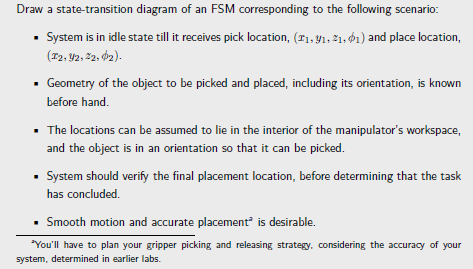

## FSM Implementation

Before making the entire FSM let us first create a simpler version for it

Lets start with the idle state

setPosition([0,0,0,0]);

The joint angles as expressed in radians are


jointAngles =      0     0     0     0


the modded joint angles are


new_theta =      0     0     0     0


serPort COM5is in use.   Closing it.


i = 4

The map theeta is \n


map_theta =    -1.5708   -1.5708         0         0         0


arb = Arbotix('port','COM10', 'nservos',5);

serPort COM10is in use.   Closing it.


open failed


ans =     'Open failed: Port: COM10 is not available. No ports are available.
     Use INSTRFIND to determine if other instrument objects are connected to the requested device.'


arb.setpos(5,0,64) %In idle state the robot has a open jaw

Error using serial/fwrite
Unsuccessful write: OBJ must be connected to the hardware with
FOPEN.

Error in Arbotix/command (line 636)
            fwrite(arb.serPort, out);

Error in Arbotix/writedata2 (

Let the position 

We will make two assumptions, firstly the workspace is reduced to the area where phi is $\pm \frac{\pi}2$ and objects will be place at the ground, which translated to approximately z = -1;

disp('Give the pick coordinates')

Give the pick coordinates


%x = input('x = '); y = input('y = '); z = input('z = ')
x = 16;y = -16; z=-1; phi = -pi/2;
%Assume x, y, z, phi = 16,-16,5,-pi/2
% Our assumption was that the pick coordinates were correct, i.e. in the
% workspace


findOptimalSolution(15,-15,2,pi/2)

serPort COM5is in use.   Closing it.


i = 4

ans =    -0.7854   -0.4784         0    2.0492


Convert pick coordinates

joint_angles = findOptimalSolution(x, y, z+5, phi)

serPort COM5is in use.   Closing it.


i = 4

joint_angles =    -0.7854    0.2674         0   -1.8382



% setPosition(joint_angles);
% curr = arb.getCurrentPose();
% if ~(curr == joint_angles)
%     disp('error')
% end

 Grab the object and close the jaws

%Now since we are just above the object, we shall open the arms jaw
joint_angles = findOptimalSolution(x, y, z, phi)

serPort COM5is in use.   Closing it.


i = 4

joint_angles =    -0.7854    0.0530         0   -1.6238


setPosition(joint_angles);

The joint angles as expressed in radians are


jointAngles =    -0.7854    0.0530         0   -1.6238


the modded joint angles are


new_theta =    -0.7854    0.0530         0   -1.6238


serPort COM5is in use.   Closing it.


i = 4

The map theeta is \n


map_theta =    -2.3562   -1.5178         0   -1.6238         0


arb = Arbotix('port','COM5', 'nservos',5);

serPort COM5is in use.   Closing it.


i = 4

arb.setpos(5,1.25,64) % CLose the jaws, adjust the length according to the the the cube


place coordinates

x_place = -10;y_place = -16; z_place=-1; phi = -pi/2;
%Assume x, y, z, phi = 16,-16,5,-pi/2
if 1%In_WKSP(x, y)
    % Will implement the worksapce check function
    joint_angles = findOptimalSolution(x_place, y_place, z_place + 5, phi)
    setPosition(joint_angles);
    joint_angles = findOptimalSolution(x_place, y_place, z_place, phi)
    setPosition(joint_angles);
    arb = Arbotix('port','COM10', 'nservos',5);
    arb.setpos(5,0,64) %open jaw
    setPosition([0,0,0,0])
else 
    %Go back to idle position
    setPosition([0,0,0,0])
    arb.setpos(5,0,64) %open jaw
end

serPort COM5is in use.   Closing it.


i = 4

joint_angles =     1.0122   -0.0866    0.8081   -2.2924


The joint angles as expressed in radians are


jointAngles =     1.0122   -0.0866    0.8081   -2.2924


the modded joint angles are


new_theta =     1.0122   -0.0866    0.8081   -2.2924


serPort COM5is in use.   Closing it.


i = 4

The map theeta is \n


map_theta =    -0.5586   -1.6574    0.8081   -2.2924         0


serPort COM5is in use.   Closing it.


i = 4

joint_angles =     1.0122   -0.4413    1.0096   -2.1391


The joint angles as expressed in radians are


jointAngles =     1.0122   -0.4413    1.0096   -2.1391


the modded joint angles are


new_theta =     1.0122   -0.4413    1.0096   -2.1391


serPort COM5is in use.   Closing it.


i = 4

The map theeta is \n


map_theta =    -0.5586   -2.0121    1.0096   -2.1391         0


serPort COM10is in use.   Closing it.


open failed


ans =     'Open failed: Port: COM10 is not available. No ports are available.
     Use INSTRFIND to determine if other instrument objects are connected to the requested device.'


Error using serial/fwrite
Unsuccessful write: OBJ must be connected to the hardware with
FOPEN.

Error in Arbotix/command (line 636)
            fwrite(arb.serPort, out);

Error in Arbotix/writedata2 (

#### Explaination of In_WKSP(x, y) function

Since the minium DH Joint angle is -60 and max joint angle is 240, 

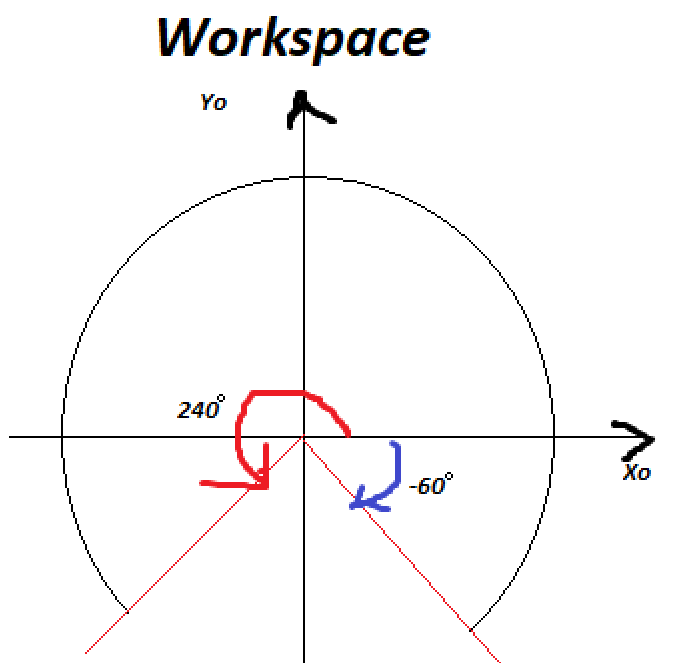

The joint angles should be within this range specified by the diagram above, i.e. $\theta \in [0, 240] 
$ or  $\theta \in [300, 360)$ ($0\leq \theta \leq240$ or $300\leq \theta <360$)

x = 20;y = -22; z=-1; phi = -pi/2;
In_WKSP(x, y)

Quadrant = 4 
theta = 3.122737e+02 
The a = 1 
r = 29.7321 
The d = 0 
Not in the workspace


ans = 0

## Proper Implementation

    %Initialiing the state variables
q = 1;

Pick = [16 -16 -1 -pi/2];
place = [-10 -16 -1 -pi/2];
idle = [0 0 0 0];
verify = 0;
p1 = 0; p2 = 0; pl1 = 0; pl2 = 0; c1 = 0;
while q 
    
    
    
    
    error = 0; %if error is zero no error has occured 
    
    % Verify the place location
    % Given the constraint, i.e phi = -pi/2 and z = -1;
    a2 = 10.8; a3 = 10.8;
    r = a2 + a3;
    xPick = Pick(1); yPick = Pick(2); zPick = Pick(3); phiPick = Pick(4); 
    xPlace = place(1); yPlace = place(2); zPlace = place(3); phiPlace = place(4);
    rPlace = sqrt(xPlace^2+yPlace^2);
    if (rPlace <= r)
        verify = 1;
    end
    
    % Starting from the idle state
    setPosition(idle)
q = 0;
end

serPort COM10is in use.   Closing it.


open failed


ans =     'Open failed: Port: COM10 is not available. No ports are available.
     Use INSTRFIND to determine if other instrument objects are connected to the requested device.'


 
arb = 
Arbotix chain on serPort COM10 (closed)
 5 servos in chain                     


Error using serial/fwrite
Unsuccessful write: OBJ must be connected to the hardware with
FOPEN.

Error in Arbotix/command (line 636)
            fwrite(arb.serPort, out);

Error in Arbotix/writedata2 (

state = 'id9e'

state = 'id9e'

str_comp(state, 'id9e')

ans = 1